# Channel Matched Precoder

% Downlink
% Max Rate V.S. Number of Antennas
% Linear and Rectangular Formation


## Global Parameter

clc;
clearvars;

K = 10;
dn = 0.5;

taps = 4;
freq = 4;

use = 5;

time = 100;
cyclic_prefix = 20;

shield = taps + freq + 1;
IK = eye(K);

M1_all = [4, 8, 8, 16, 16];
M2_all = [8, 8, 16, 16, 32];
M_all = M1_all .* M2_all;
sample = 5;

alpha = 0.99;
eta = 500;
mu = 0;


## Channel Power Delay Profile

u = (0 : K - 1) / 5;
for l = 1 : taps
    for k = 1 : K
        d1 = exp(-1 * u(k) * (0 : taps - 1));
        d(l, k) = exp(-1 * u(k) * (l - 1)) / (sum(d1));
    end
    D1 = diag(d(l, :));
    D(:, :, l) = D1;
end


## Search Tree

for index = 1 : sample
    
    % Settings
    M = M_all(index);
    M1 = M1_all(index);
    M2 = M2_all(index);
    
    % Linear
    for i = 1 : M
        for j = 1 : M
            dist(i, j) = abs(i - j) * dn;
        end
    end
    exp_1D = alpha .^ dist;
    arg = eta ^ 2 - 4 * (pi ^ 2) .* (dist) .^ 2 + 4i * pi * eta * sin(mu) .* dist;
    arg = sqrt(arg);
    bsl_1D = abs(besseli(0, arg) ./ besseli(0, eta));
    clear dist;
    
    % Rectangular
    i = 1;
    for c1 = 1 : M1
        for r1 = 1 : M2
            j = 1;
            for c2 = 1 : M1
                for r2 = 1 : M2
                    dist(i, j) = (c2 - c1) ^ 2 + (r1 - r2) ^ 2;
                    j = j + 1;
                end
            end
            i = i + 1;
        end
    end
    dist = sqrt(dist .* dn);
    exp_2D = alpha .^ dist;
    arg = eta ^ 2 - 4 * (pi ^ 2) .* (dist) .^ 2 + 4i * pi * eta * sin(mu) .* dist;
    arg = sqrt(arg);
    bsl_2D = abs(besseli(0, arg) ./ besseli(0, eta));
    clear dist;
    
    %{
    
    for n = 1: use
        S(:, :, n) = (sqrt(0.5)) * (randn(K, time) + 1i * randn(K, time));
        Z(:, :, n) = (sqrt(0.5)) * (randn(K, time) + 1i * randn(K, time));
        
        for l = 1: taps
            D1 = D(:, :, l) .^ (0.5);
            H1 = (sqrt(0.5)) * (randn(M, K) + 1i * randn(M, K));
            
            Hl_exp_1D(:, :, l, n) = conj((exp_1D ^ (0.5)) * H1) * D1;
            Hl_bsl_1D(:, :, l, n) = conj((bsl_1D ^ (0.5)) * H1) * D1;
            Hl_exp_2D(:, :, l, n) = conj((exp_2D ^ (0.5)) * H1) * D1;
            Hl_bsl_2D(:, :, l, n) = conj((bsl_2D ^ (0.5)) * H1) * D1;
        end
    
        Hv1 = fft(Hl_exp_1D(:, :, :, n), freq, 3);
        Hv2 = fft(Hl_bsl_1D(:, :, :, n), freq, 3);
        Hv3 = fft(Hl_exp_2D(:, :, :, n), freq, 3);
        Hv4 = fft(Hl_bsl_2D(:, :, :, n), freq, 3);
        for v = 1: freq
            Fv = Hv1(:, :, v);
            Wv1(:, :, v) = Fv;
            clear Fv;
            Fv = Hv2(:, :, v);
            Wv2(:, :, v) = Fv;
            clear Fv;
            Fv = Hv3(:, :, v);
            Wv3(:, :, v) = Fv;
            clear Fv;
            Fv = Hv4(:, :, v);
            Wv4(:, :, v) = Fv;
            clear Fv;
        end
        Wl_exp_1D(:, :, :, n) = ifft(Wv1, freq, 3);
        Wl_bsl_1D(:, :, :, n) = ifft(Wv2, freq, 3);
        Wl_exp_2D(:, :, :, n) = ifft(Wv3, freq, 3);
        Wl_bsl_2D(:, :, :, n) = ifft(Wv4, freq, 3);
        
        clear Wv1 Wv2 Wv3 Wv4;
    
        [AX1(n)] = Signal_Power(freq, Wl_exp_1D(:, :, :, n));
        [AX2(n)] = Signal_Power(freq, Wl_bsl_1D(:, :, :, n));
        [AX3(n)] = Signal_Power(freq, Wl_exp_2D(:, :, :, n));
        [AX4(n)] = Signal_Power(freq, Wl_bsl_2D(:, :, :, n));
    
        % Composite Effect Matrix
        for k = 1: K
            for l = 0: (taps - 1)
                V1 = Hl_exp_1D(:, :, l + 1, n) * IK(:, k);
                V2 = Wl_exp_1D(:, :, l + 1, n) * IK(:, k);
                X1(l + 1) = V1' * V2;
                clear V1 V2;
                V1 = Hl_bsl_1D(:, :, l + 1, n) * IK(:, k);
                V2 = Wl_bsl_1D(:, :, l + 1, n) * IK(:, k);
                X2(l + 1) = V1' * V2;
                clear V1 V2;
                V1 = Hl_exp_2D(:, :, l + 1, n) * IK(:, k);
                V2 = Wl_exp_2D(:, :, l + 1, n) * IK(:, k);
                X3(l + 1) = V1' * V2;
                clear V1 V2;
                V1 = Hl_bsl_2D(:, :, l + 1, n) * IK(:, k);
                V2 = Wl_bsl_2D(:, :, l + 1, n) * IK(:, k);
                X4(l + 1) = V1' * V2;
                clear V1 V2;
            end
            EX1(k, n) = sum(X1);
            EX2(k, n) = sum(X2);
            EX3(k, n) = sum(X3);
            EX4(k, n) = sum(X4);
            clear X1 X2 X3 X4;
        end
    end
    a1 = mean(AX1);
    a2 = mean(AX2);
    a3 = mean(AX3);
    a4 = mean(AX4);
    clear AX1 AX2 AX3 AX4;
    
    % Received Signals and Desired Signals
    Y1 = zeros(K, time, use);
    Y2 = zeros(K, time, use);
    Y3 = zeros(K, time, use);
    Y4 = zeros(K, time, use);
    for n = 1: use
        for k = 1: K
            for l = 0: (taps - 1)
                V1 = Hl_exp_1D(:, :, l + 1, n) * IK(:, k);
                V2 = Hl_bsl_1D(:, :, l + 1, n) * IK(:, k);
                V3 = Hl_exp_2D(:, :, l + 1, n) * IK(:, k);
                V4 = Hl_bsl_2D(:, :, l + 1, n) * IK(:, k);
                for m = 0: (freq - 1)
                    V5 = Wl_exp_1D(:, :, m + 1, n);
                    V6 = Wl_bsl_1D(:, :, m + 1, n);
                    V7 = Wl_exp_2D(:, :, m + 1, n);
                    V8 = Wl_bsl_2D(:, :, m + 1, n);
                    Y1(k, shield: time, n) = Y1(k, shield: time, n) + (V1' * V5 * S(:, (shield : time) - m - l, n));
                    Y2(k, shield: time, n) = Y2(k, shield: time, n) + (V2' * V6 * S(:, (shield : time) - m - l, n));
                    Y3(k, shield: time, n) = Y3(k, shield: time, n) + (V3' * V7 * S(:, (shield : time) - m - l, n));
                    Y4(k, shield: time, n) = Y4(k, shield: time, n) + (V4' * V8 * S(:, (shield : time) - m - l, n));
                end
            end
            X1(k, 1 : time, n) = mean(EX1(k, :)) * S(k, 1 : time, n) / a1;
            X2(k, 1 : time, n) = mean(EX2(k, :)) * S(k, 1 : time, n) / a2;
            X3(k, 1 : time, n) = mean(EX3(k, :)) * S(k, 1 : time, n) / a3;
            X4(k, 1 : time, n) = mean(EX4(k, :)) * S(k, 1 : time, n) / a4;
            
            clear V1 V2 V3 V4 V5 V6 V7 V8;
        end
    end
    
    clear Hl_exp_1D Hl_bsl_1D Hl_exp_2D Hl_bsl_2D;
    clear Wl_exp_1D Wl_bsl_1D Wl_exp_2D Wl_bsl_2D;
    clear EX1 EX2 EX3 EX4;
    
    % Effective Noise
    Z1(:, 1 : (shield - 1), :) = (Y1(:, 1 : (shield - 1), :) / a1);
    Z1(:, shield : time, :) = (Y1(:, shield : time, :) / a1) - X1(:, shield : time, :);
    Z2(:, 1 : (shield - 1), :) = (Y2(:, 1 : (shield - 1), :) / a2);
    Z2(:, shield : time, :) = (Y2(:, shield : time, :) / a2) - X2(:, shield : time, :);
    Z3(:, 1 : (shield - 1), :) = (Y3(:, 1 : (shield - 1), :) / a3);
    Z3(:, shield : time, :) = (Y3(:, shield : time, :) / a3) - X3(:, shield : time, :);
    Z4(:, 1 : (shield - 1), :) = (Y4(:, 1 : (shield - 1), :) / a4);
    Z4(:, shield : time, :) = (Y4(:, shield : time, :) / a4) - X4(:, shield : time, :);
    clear Y1 Y2 Y3 Y4;
    
    for n = 1: use
        for k = 1: K
            Sn1 = mean(abs(X1(k, :, n)) .^ 2);
            Sn2 = mean(abs(X2(k, :, n)) .^ 2);
            Sn3 = mean(abs(X3(k, :, n)) .^ 2);
            Sn4 = mean(abs(X4(k, :, n)) .^ 2);
            
            Vn1 = mean(abs(Z1(k,:, n)) .^ 2);
            Vn2 = mean(abs(Z2(k,:, n)) .^ 2);
            Vn3 = mean(abs(Z3(k,:, n)) .^ 2);
            Vn4 = mean(abs(Z4(k,:, n)) .^ 2);
            
            SNR1 = Sn1 / Vn1;
            SNR2 = Sn2 / Vn2;
            SNR3 = Sn3 / Vn3;
            SNR4 = Sn4 / Vn4;
            
            Rk1(k, n) = 0.5 * log2(1 + SNR1);
            Rk2(k, n) = 0.5 * log2(1 + SNR2);
            Rk3(k, n) = 0.5 * log2(1 + SNR3);
            Rk4(k, n) = 0.5 * log2(1 + SNR4);
        end
    end
    
    R1(index) = mean(sum(Rk1, 1));
    R2(index) = mean(sum(Rk2, 1));
    R3(index) = mean(sum(Rk3, 1));
    R4(index) = mean(sum(Rk4, 1));
    
    clear X1 X2 X3 X4;
    clear Z1 Z2 Z3 Z4;
    clear Rk1 Rk2 Rk3 Rk4;
    
    Sn0 = (M / K);
    Vn0 = 1;
    SNR0 = Sn0 / Vn0;
    C0(index) = (K / 2) * log2(1 + Sn0);
    R0(index) = (K / 2) * log2(1 + SNR0);
    
    clear S Z;
    
    %}

## Mathematical Results

    Sn0 = (M / K);
    SNR0 = Sn0;
    
    Vn1 = ((trace(exp_1D * exp_1D')) / M);
    SNR1 = Sn0 / Vn1;
    
    Vn2 = ((trace(bsl_1D * bsl_1D')) / M);
    SNR2 = Sn0 / Vn2;
    
    Vn3 = ((trace(exp_2D * exp_2D')) / M);
    SNR3 = Sn0 / Vn3;
    
    Vn4 = ((trace(bsl_2D * bsl_2D')) / M);
    SNR4 = Sn0 / Vn4;
    
    R1(index) = (K / 2) * log2(1 + SNR1);
    R2(index) = (K / 2) * log2(1 + SNR2);
    R3(index) = (K / 2) * log2(1 + SNR3);
    R4(index) = (K / 2) * log2(1 + SNR4);
    
end

factor = (time) / (time + cyclic_prefix);

R1 = factor * R1;
R2 = factor * R2;
R3 = factor * R3;
R4 = factor * R4;


## Visualization

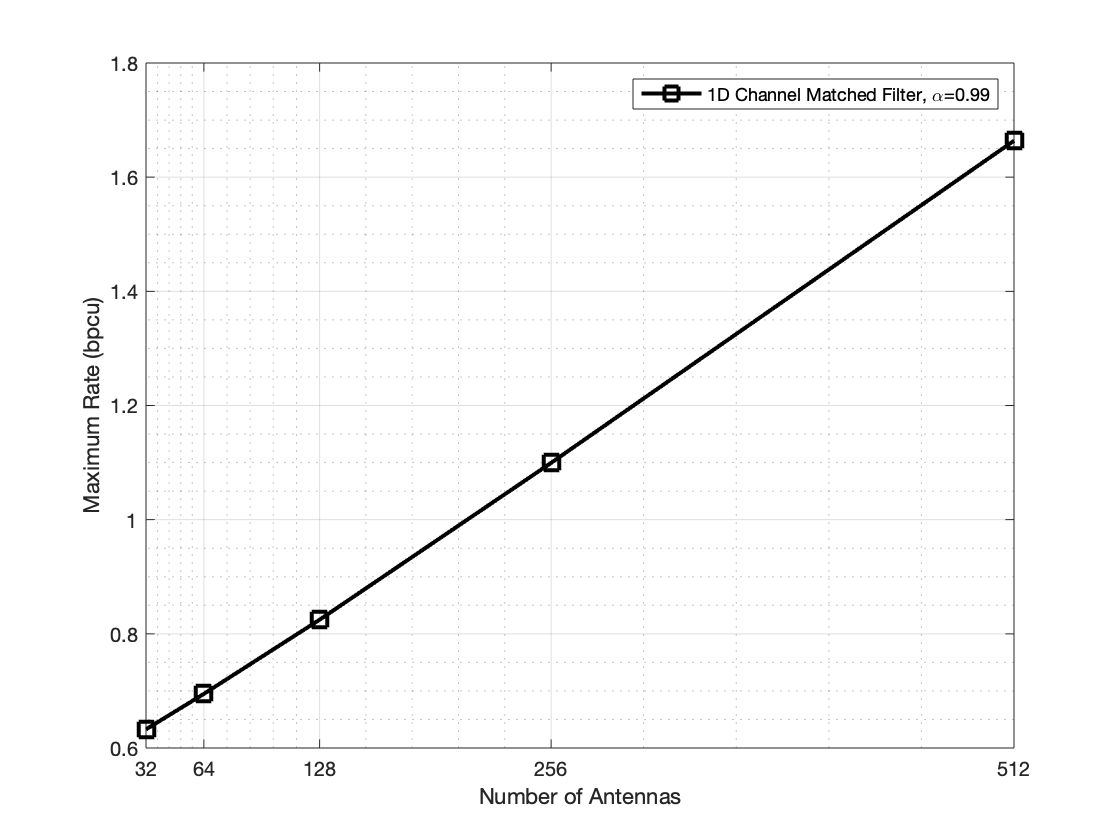

angel = strcat('\pi/', num2str(pi / mu));
if (mu == 0)
    angel = num2str(0);
end

name_a = '1D Channel Matched Filter';
name_b = '2D Channel Matched Filter';

name1 = strcat(name_a, ', \alpha=', num2str(alpha));
% name2 = strcat(name_a, ', \eta=', num2str(eta), ', \mu=', angel);
name2 = strcat(name_a, ', \eta=', num2str(eta));
name3 = strcat(name_b, ', \alpha=', num2str(alpha));
% name4 = strcat(name_b, ', \eta=', num2str(eta), ', \mu=', angel);
name4 = strcat(name_b, ', \eta=', num2str(eta));

x_label = 'Number of Antennas';
y_label = 'Maximum Rate (bpcu)';
style = '-ks';

figure;
plot(M_all, R1, style, 'DisplayName', name1, 'MarkerSize', 10);

ylabel(y_label, 'fontsize', 10);
xlabel(x_label, 'fontsize', 10);
set(gca, 'fontsize', 10);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
xticks(M_all);
xlim([M_all(1), M_all(sample)]);
legend();
grid on;
grid minor;

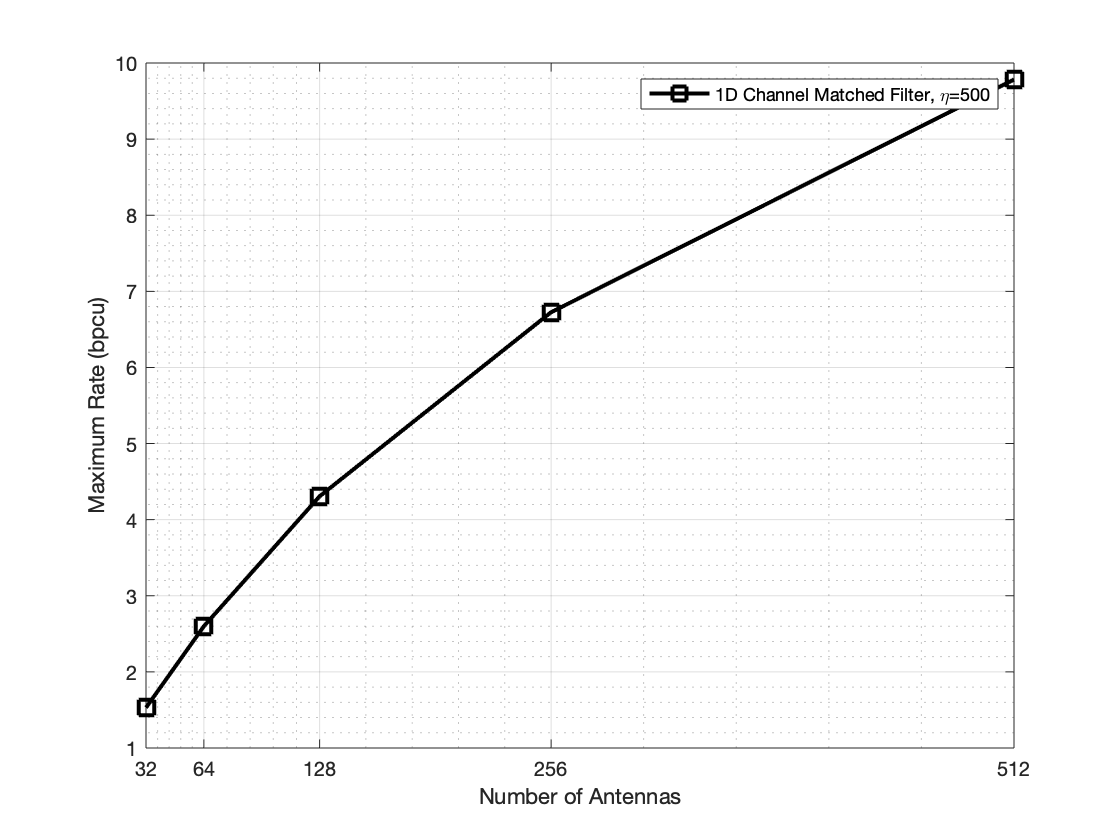



figure;
plot(M_all, R2, style, 'DisplayName', name2, 'MarkerSize', 10);

ylabel(y_label, 'fontsize', 10);
xlabel(x_label, 'fontsize', 10);
set(gca, 'fontsize', 10);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
xticks(M_all);
xlim([M_all(1), M_all(sample)]);
legend();
grid on;
grid minor;

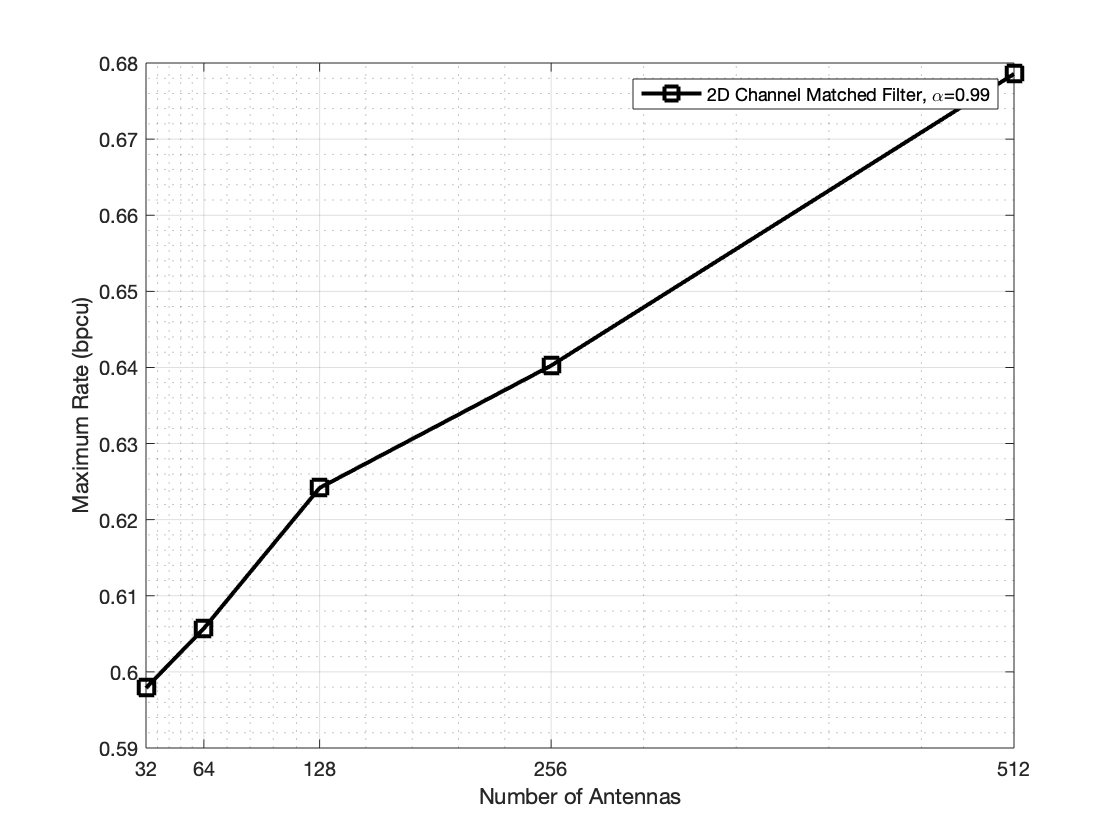



figure;
plot(M_all, R3, style, 'DisplayName', name3, 'MarkerSize', 10);

ylabel(y_label, 'fontsize', 10);
xlabel(x_label, 'fontsize', 10);
set(gca, 'fontsize', 10);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
xticks(M_all);
xlim([M_all(1), M_all(sample)]);
legend();
grid on;
grid minor;

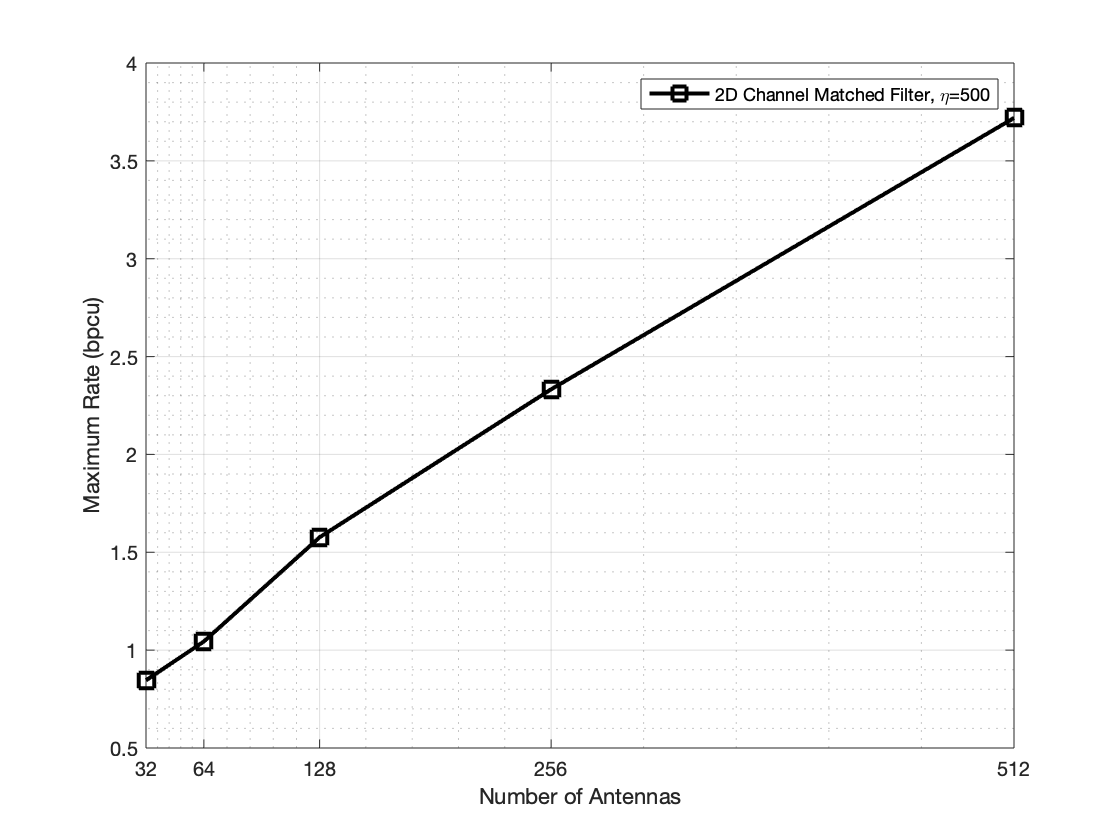



figure;
plot(M_all, R4, style, 'DisplayName', name4, 'MarkerSize', 10);

ylabel(y_label, 'fontsize', 10);
xlabel(x_label, 'fontsize', 10);
set(gca, 'fontsize', 10);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
xticks(M_all);
xlim([M_all(1), M_all(sample)]);
legend();
grid on;
grid minor;